# TDoA solution and Isochrones

% clear;clc

#### Create and transform hyperbola

% Initialize sensor positions
% sensor_pos = [00e3 20e3 40e3 00e3 ;
%               00e3  00e3 00e3  -25e3];

% Initialize Source position
emitter_pos = [-5749.20697309158;
               -46335.2520706034];

pri = 1e-3;
time = 1;
c = 3e8;


#### TOA Generator function

[nSensors, nEmitter, sensor_pos, emitter_pos, emitter_init, reported_toa] = toa_generator(sensor_pos,emitter_pos,pri,time,false);

#### Form the Isochrones

for n = 1:nEmitter
    ranges{n} = vecnorm(sensor_pos - emitter_pos(:,n));
end

% Central sensor pairing (ref sensor = s_1)
tdoaPairs(:,2) = (2:(nSensors))';
tdoaPairs(:,1) = 1;

for n = 1:nEmitter
    for i = 1:size(tdoaPairs,1)
            iso{n,i} = draw_2Disochrone(sensor_pos(:,1),sensor_pos(:,i+1),(ranges{n}(1)-ranges{n}(i+1)),100e3,5e3);
    end
end

#### Find the solution to the hyperbolic eqns for 2D TDoA

for n = 1:nEmitter
    for i = 1:nSensors % Assign positions to new variables
        x_s(i) = sensor_pos(1,i);
        y_s(i) = sensor_pos(2,i);
        t(i) = reported_toa{n}(i,1);
    end

    %% Evaluate equations
    syms x y
    s1 = eval(sqrt((x_s(1) - x)^2 + (y_s(1) - y)^2) - sqrt((x_s(2) - x)^2 + (y_s(2) - y)^2)  == c*(t(1) - t(2)));
    s2 = eval(sqrt((x_s(1) - x)^2 + (y_s(1) - y)^2) - sqrt((x_s(3) - x)^2 + (y_s(3) - y)^2)  == c*(t(1) - t(3)));
    
    % Solve eqns for (x,y) given the values of other eqn variables 
    sol = solve([s1 s2],[x y]);
    
    % Extract 2D soln
    xsol = sol.x;
    ysol = sol.y;
    
    % Compile solution
    solu{n} = [(eval(xsol)).';(eval(ysol)).'];
end

#### Plotting the results and the solution(s)

Plot sensor positions and label

% Plot sensor positions
figure;grid on
hold on
for j = 1:(nSensors)
    lbl_sen = sprintf('S_{%1.0d}',j);
    hold on
    % Plot sensor positions
    sens = scatter(sensor_pos(1,j)/1e3, sensor_pos(2,j)/1e3,'blue','filled','o','DisplayName','Sensors', ...
                   'MarkerEdgeColor','k','LineWidth',0.5);
    text(sensor_pos(1,j)/1e3 +.2, sensor_pos(2,j)/1e3-.2,lbl_sen);
    if j ~=1
        excludeFromLegend(sens);
    end
end

Plot emitter position(s)

% Plot emitter positions
hold on
for i = 1:nEmitter
    em = scatter(emitter_pos(1,i)/1e3,emitter_pos(2,i)/1e3,'red','filled','^','DisplayName','Transmitter', ...
                 'MarkerEdgeColor','k','LineWidth',0.5);
    lbl_tx = sprintf('T_%1.0f',i);
    text(emitter_pos(1,i)/1e3 +.2,emitter_pos(2,i)/1e3+.2,lbl_tx);
    if i ~=1
        excludeFromLegend(em);
    end
end


Plot isochrones and solution overlays

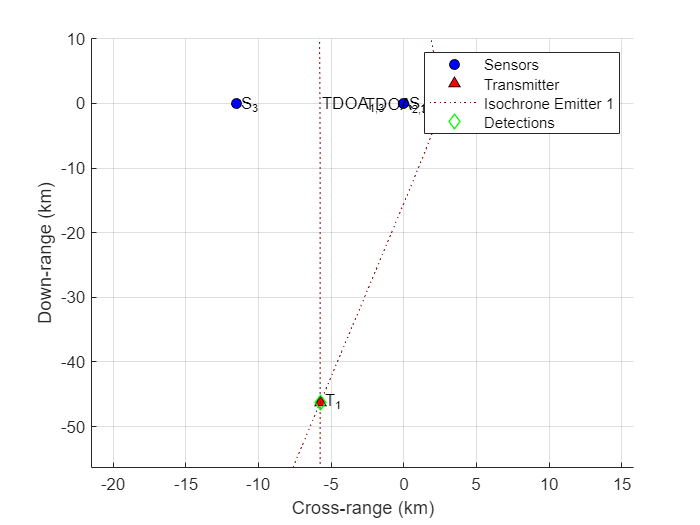

% Apply colour jet for multiple emitters
cm = turbo(nEmitter);
for n = 1:nEmitter
    for i = 1:nSensors-1
        lbl_iso = sprintf('Isochrone Emitter %1.0d',n);         % Isochrone labels
        iso_obj = plot(iso{n,i}(1,:)/1e3,iso{n,i}(2,:)/1e3,'LineStyle',':','DisplayName',lbl_iso,Color=cm(n,:));
        if i ~=1
            excludeFromLegend(iso_obj);                           % Exclude multiple labels
        end
        % TDOA and Sensor lables
        if nEmitter<2
            lbl = sprintf('TDOA_{%1.0d,%1.0d}',i,nSensors);     % Label Isochrones only if single emitter (otherwise clutter)
            text(mean([sensor_pos(1,i)/1e3,sensor_pos(1,end)/1e3]),mean([sensor_pos(2,i)/1e3,sensor_pos(2,end)/1e3])-.2,lbl);
        end
    end
    % Plot solutions
    sol_obj = scatter(solu{n}(1,:)/1e3,solu{n}(2,:)/1e3,'green','diamond','LineWidth',1,'DisplayName','Detections');
    if n > 1
        excludeFromLegend(sol_obj);                           % Exclude multiple labels
    end

end

hold on
% Adjust Axes
lim_x = [min([sensor_pos(1,:)/1e3 emitter_pos(1,:)/1e3]) - 10 max([sensor_pos(1,:)/1e3 emitter_pos(1,:)/1e3]) + 10];
lim_y = [min([sensor_pos(2,:)/1e3 emitter_pos(2,:)/1e3]) - 10  max([sensor_pos(2,:)/1e3 emitter_pos(2,:)/1e3]) + 10];
xlim(lim_x); ylim(lim_y)

xlabel('Cross-range (km)');ylabel('Down-range (km)');
legend('Location','northeast');